# Inizializzazione

clear
close all
clc

mot.k = 5.2;
mot.T = 0.03;
s = tf('s');
P = mot.k / (s * (mot.T * s + 1));
Pn = P;
Q = 1 / (0.005 * s + 1);

Guy = minreal(P * Pn / (Pn + Q * (P - Pn)), 1e-6);
Gdy = minreal(P * Pn * (1 - Q) / (Pn + Q * (P - Pn)), 1e-6);
Gny = minreal(P * Q / (Pn + Q * (P - Pn)), 1e-6);

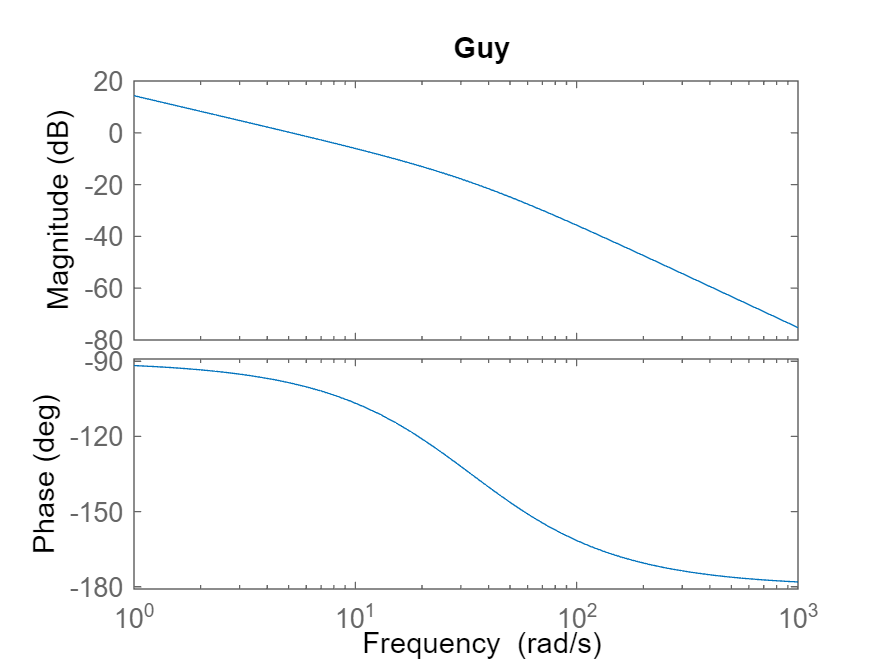

figure
bode(Guy)
title("Guy")

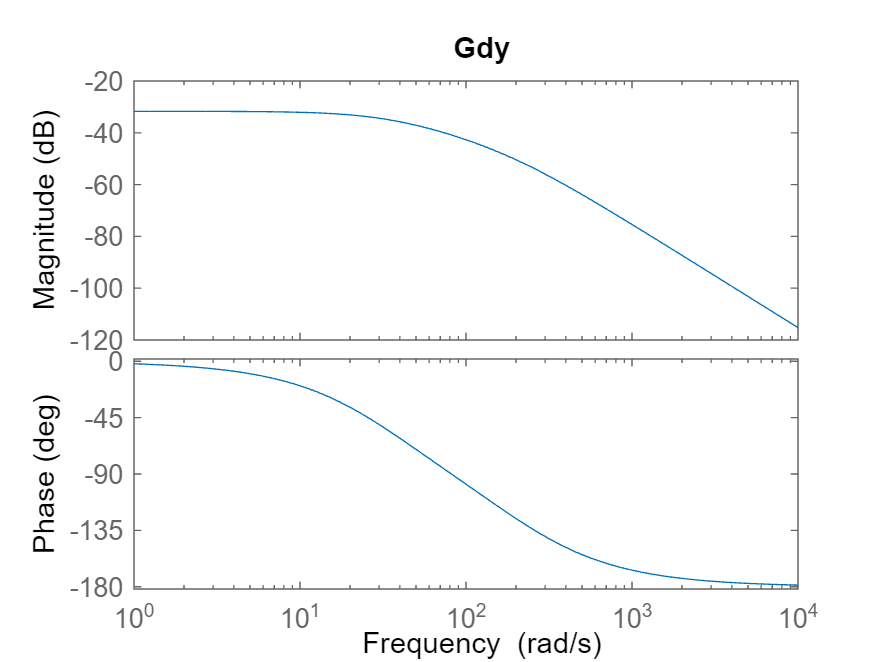

figure
bode(Gdy)
title("Gdy")

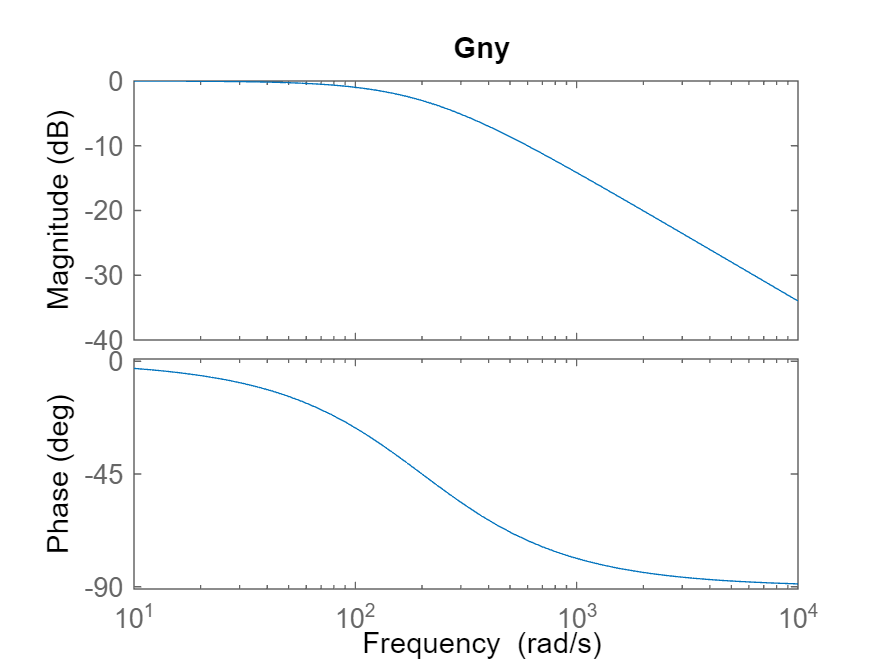

figure
bode(Gny)
title("Gny")

Pn2 = 5 / (s * (0.05 * s + 1));
Guy2 = minreal(P * Pn2 / (Pn2 + Q * (P - Pn2)), 1e-6);
Gdy2 = minreal(P * Pn2 * (1 - Q) / (Pn2 + Q * (P - Pn2)), 1e-6);
Gny2 = minreal(P * Q / (Pn2 + Q * (P - Pn2)), 1e-6);

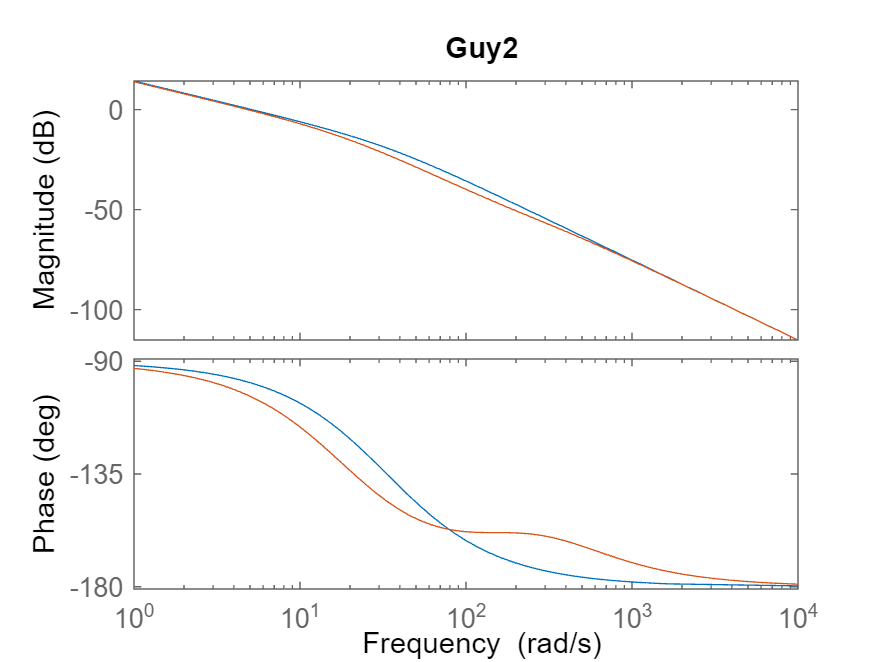

figure
hold on
bode(Guy)
bode(Guy2)
title("Guy2")

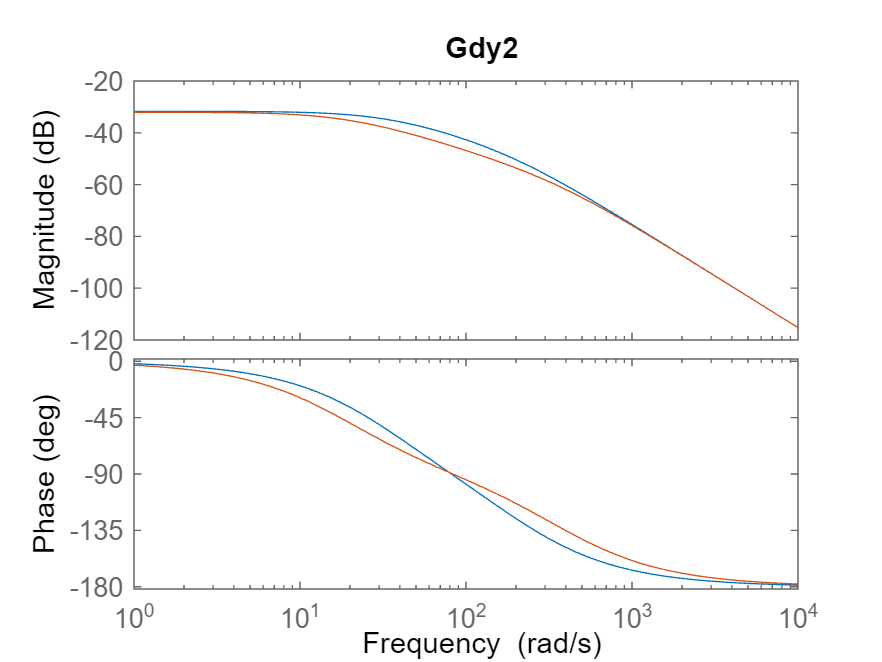

figure
hold on
bode(Gdy)
bode(Gdy2)
title("Gdy2")

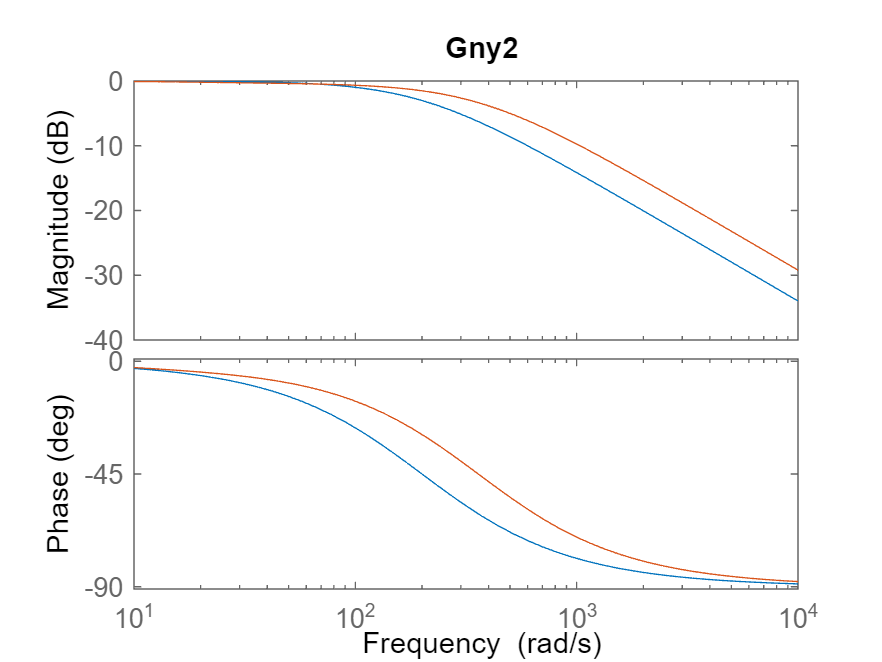

figure
hold on
bode(Gny)
bode(Gny2)
title("Gny2")